clear all
close all

# Trajectory Generation

## Load Parameters

CONSTANTS.N = 45; % Order of approximation
N = CONSTANTS.N;
CONSTANTS.init = [1;2;3;-1;-1;-1];
CONSTANTS.fin = [0;0;0;0;0;0];
CONSTANTS.umax = 1;

## Initial guess

x1 = linspace(CONSTANTS.init(1),CONSTANTS.fin(1),N+1)';
x2 = linspace(CONSTANTS.init(2),CONSTANTS.fin(2),N+1)';
x3 = linspace(CONSTANTS.init(3),CONSTANTS.fin(3),N+1)';
x4 = linspace(CONSTANTS.init(4),CONSTANTS.fin(4),N+1)';
x5 = linspace(CONSTANTS.init(5),CONSTANTS.fin(5),N+1)';
x6 = linspace(CONSTANTS.init(6),CONSTANTS.fin(6),N+1)';
u1 = zeros(N+1,1);
u2 = zeros(N+1,1);
u3 = zeros(N+1,1);
T = 1;
x0 = [x1;x2;x3;x4;x5;x6;u1;u2;u3;T];

## Linear Constraints and UL Bounds

A=[]; b=[]; Aeq=[]; beq=[]; lb=[]; ub=[]; 

## Optimize

options = optimoptions(@fmincon,'Algorithm','sqp','MaxFunctionEvaluations',3000000);
tic
[x,fval] = fmincon(@(x)costfun(x,CONSTANTS),x0,A,b,Aeq,beq,lb,ub,@(x)nonlcon(x,CONSTANTS),options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc

Elapsed time is 3.287110 seconds.


## Plot

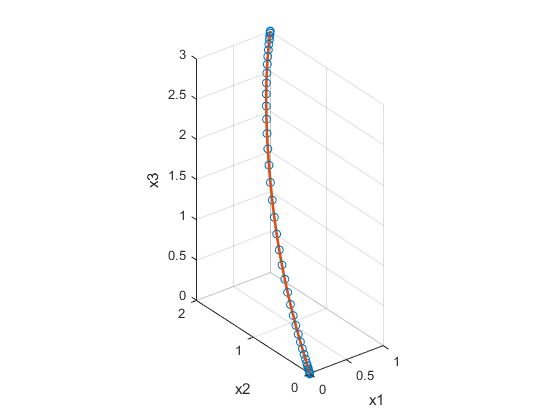

N = CONSTANTS.N;

%% Grab Trajectories

x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
x3 = x(2*N+3:3*N+3);
x4 = x(3*N+4:4*N+4);
x5 = x(4*N+5:5*N+5);
x6 = x(5*N+6:6*N+6);
u1 = x(6*N+7:7*N+7);
u2 = x(7*N+8:8*N+8);
u3 = x(8*N+9:9*N+9);
T = x(end);

[tnodes,w,Diff] = LGL_PS(CONSTANTS.N,T);


%% Plot
t = 0:0.01:T;
figure
plot3(x1,x2,x3,'o'); hold on
plot3(LagrangePoly(x1',tnodes,t),LagrangePoly(x2',tnodes,t),LagrangePoly(x3',tnodes,t),'Linewidth',2);
xlabel('x1'); ylabel('x2'); zlabel('x3')
grid on
axis equal

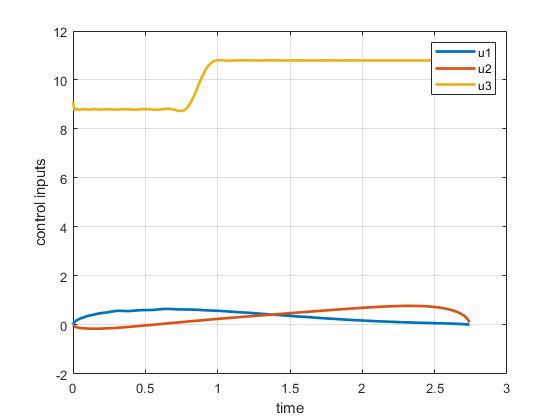

figure
plot(t,LagrangePoly(u1',tnodes,t),'Linewidth',2); hold on
plot(t,LagrangePoly(u2',tnodes,t),'Linewidth',2);
plot(t,LagrangePoly(u3',tnodes,t),'Linewidth',2);
xlabel('time'); ylabel('control inputs'); 
legend('u1','u2','u3');
grid on

## Cost Function

function J = costfun(x,CONSTANTS)
%COSTFUN Summary of this function goes here
N = CONSTANTS.N; 
x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
x3 = x(2*N+3:3*N+3);
x4 = x(3*N+4:4*N+4);
x5 = x(4*N+5:5*N+5);
x6 = x(5*N+6:6*N+6);
u1 = x(6*N+7:7*N+7);
u2 = x(7*N+8:8*N+8);
u3 = x(8*N+9:9*N+9);
T = x(end);

J = T;
end

## Nonlinear Constraints

function [c,ceq] = nonlcon(x,CONSTANTS)
%NONLCON Summary of this function goes here
%   Detailed explanation goes here
N = CONSTANTS.N;
x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
x3 = x(2*N+3:3*N+3);
x4 = x(3*N+4:4*N+4);
x5 = x(4*N+5:5*N+5);
x6 = x(5*N+6:6*N+6);
u1 = x(6*N+7:7*N+7);
u2 = x(7*N+8:8*N+8);
u3 = x(8*N+9:9*N+9);
T = x(end);

[~,~,Diff] = LGL_PS(N,T);
 
dyn1 = x1'*Diff - x4';
dyn2 = x2'*Diff - x5';
dyn3 = x3'*Diff - x6';
dyn4 = x4'*Diff - u1';
dyn5 = x5'*Diff - u2';
dyn6 = x6'*Diff - u3' + 9.8*ones(1,N+1);





c=[u1-CONSTANTS.umax;-u1-CONSTANTS.umax;u2-CONSTANTS.umax;-u2-CONSTANTS.umax;-9.8+u3-CONSTANTS.umax;9.8-u3-CONSTANTS.umax;];
ceq=[dyn1';dyn2';dyn3';dyn4';dyn5';dyn6'; ... 
    x1(1)-CONSTANTS.init(1);x2(1)-CONSTANTS.init(2);x3(1)-CONSTANTS.init(3); ...
    x4(1)-CONSTANTS.init(4);x5(1)-CONSTANTS.init(5);x6(1)-CONSTANTS.init(6); ...
    x1(end)-CONSTANTS.fin(1);x2(end)-CONSTANTS.fin(2);x3(end)-CONSTANTS.fin(3); ...
    x4(end)-CONSTANTS.fin(4);x5(end)-CONSTANTS.fin(5);x6(end)-CONSTANTS.fin(6); ...
    ];

end